# Stochastic simulations!

July 31, 2018, PBOC Day 2

Random numbers:

n = rand()

n = 0.2958

Random walker from random numbers?

position = 0;
step_size = 1;
prob_left = 0.5;
n_time_steps = 50;
n_walkers = 1;

coin_flip = rand();
if coin_flip > prob_left
    position = position - step_size;
else 
    position = position + step_size;
end
position 

position = -1

Let's do a whole walk

step_size = 1;
prob_left = 0.5;
n_time_steps = 50;
n_walkers = 1; % don't change this
position = zeros(n_walkers,n_time_steps);

for i = 2 : n_time_steps
    coin_flip = rand();
    if coin_flip > prob_left
        position(i) = position(i-1) - step_size;
    else 
        position(i) = position(i-1) + step_size;
    end
end
position;

Plot the trajectory 

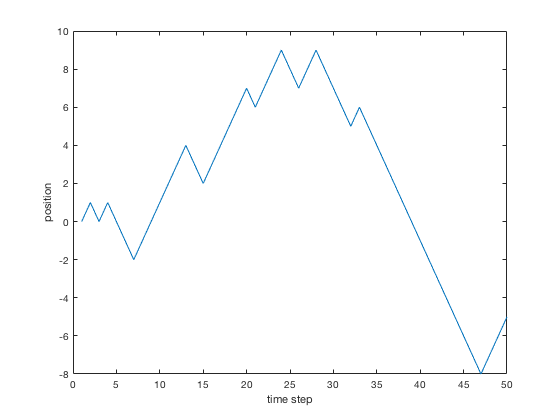

time = 1 : 1 : n_time_steps;
plot(time, position)
xlabel('time step')
ylabel('position')

Do a bunch of random walkers:

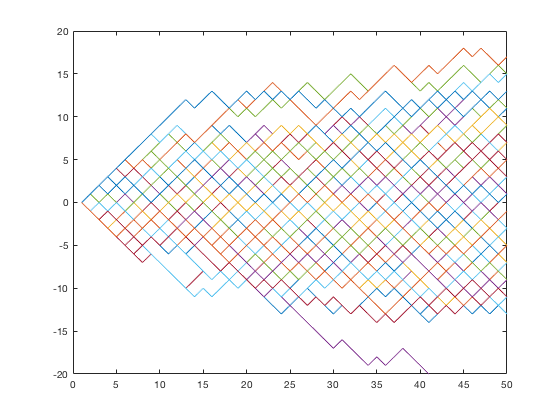

step_size = 1;
prob_left = 0.5;
n_time_steps = 50;
n_walkers = 100; 
position = zeros(n_walkers,n_time_steps);

for i = 1 : n_walkers
    for j = 2 : n_time_steps
        coin_flip = rand();
        if coin_flip > prob_left
            position(i,j) = position(i,j-1) - step_size;
        else 
            position(i,j) = position(i, j-1) + step_size;
        end 
    end
end

time = 1 : 1 : n_time_steps;
for i = 1 : n_walkers
    plot(time, position(i, :));
    ylim([-20 20])
    hold on
end

hold off

Mean displacement of walker simulation:

Mean displacement for one time step:

mean_displacement_one_step = ...
    mean(position(:, 2));

Mean displacement for all time intervals:

mean_disp = zeros(1, n_time_steps);
for b = 1 : n_time_steps
    mean_disp(b) = mean(position(:,b));
end
mean_disp

mean_disp =          0    0.0400    0.0200   -0.0800   -0.0200   -0.0800   -0.0400         0   -0.0400    0.0400    0.1200    0.2800    0.0800    0.0600   -0.0200   -0.1400   -0.2000   -0.3600   -0.4600   -0.3800   -0.4400   -0.5000   -0.5800   -0.6400   -0.7600   -0.8600   -0.7600   -0.7000   -0.7200   -0.7400   -0.8000   -0.7000   -0.7200   -0.6600   -0.7000   -0.6400   -0.6600   -0.6800   -0.7600   -0.7600   -0.7400   -0.7800   -0.7000   -0.6000   -0.5200   -0.5800   -0.5800   -0.6400   -0.5800   -0.5600


alternative approach

mean_disp = mean(position(:,:), 1)

mean_disp =          0    0.0400    0.0200   -0.0800   -0.0200   -0.0800   -0.0400         0   -0.0400    0.0400    0.1200    0.2800    0.0800    0.0600   -0.0200   -0.1400   -0.2000   -0.3600   -0.4600   -0.3800   -0.4400   -0.5000   -0.5800   -0.6400   -0.7600   -0.8600   -0.7600   -0.7000   -0.7200   -0.7400   -0.8000   -0.7000   -0.7200   -0.6600   -0.7000   -0.6400   -0.6600   -0.6800   -0.7600   -0.7600   -0.7400   -0.7800   -0.7000   -0.6000   -0.5200   -0.5800   -0.5800   -0.6400   -0.5800   -0.5600


plot things :

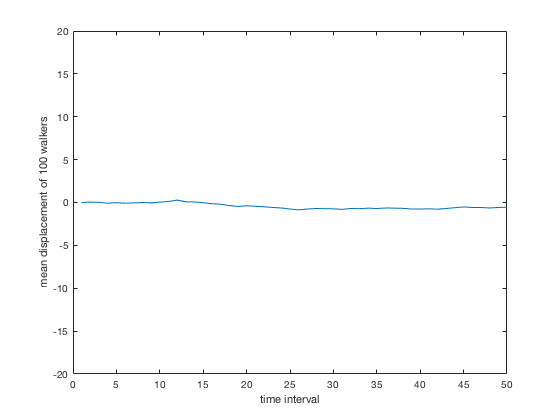

time = 1 : 1 : n_time_steps;
figure
plot(time, mean_disp)
ylim([-20 20])
xlabel('time interval')
ylabel('mean displacement of 100 walkers')

mean squared displacement

msd = mean(position.^2, 1);

plot things:

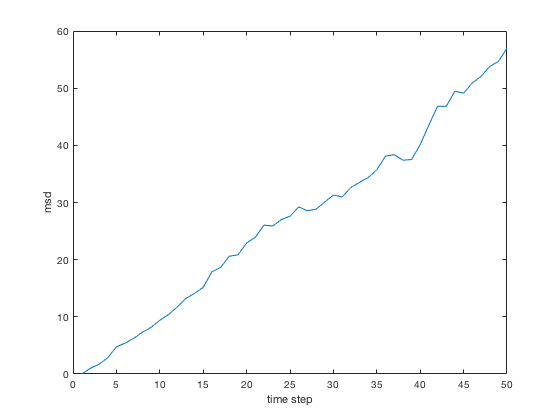

plot(time, msd)
xlabel('time step')
ylabel('msd')